Piotr Sienkiewicz    324 887

Tadeusz Chmielik   324 856

## Wczytanie pliku i analiza spektrogramu

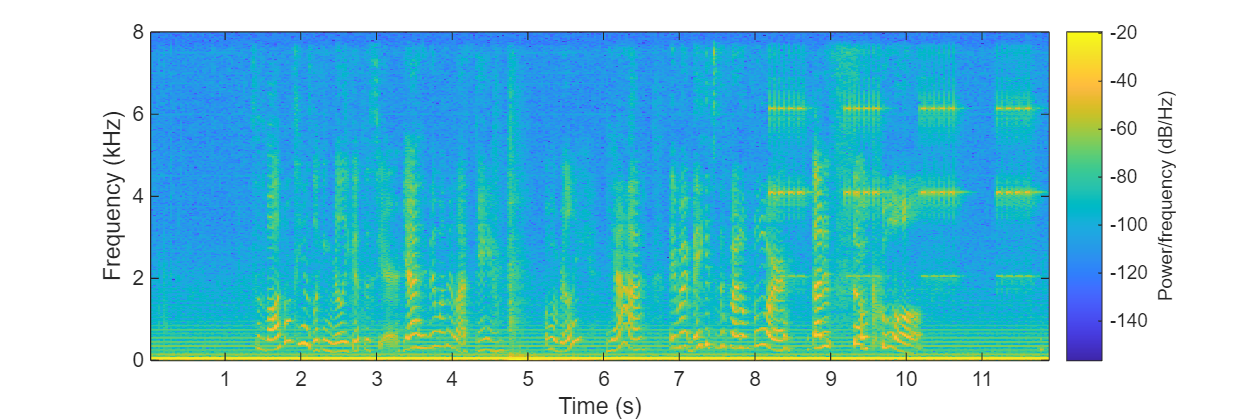

[x, fs] = audioread('data/noised.wav');

win_size = 1024;
figure('Position', [10 10 1200 400]);
spectrogram(x, blackman(win_size), win_size/2, [], fs, 'yaxis')

Na powyższym sektrogramie widać duży przedzwięk sieciowy 50Hz oraz także jego kolejne harmoniczne sięgające kilkuset herców. Dodatkowo w prawym górnym roku spektrogramu widać prążki odpowiadające dzwonieniu budzika, które leżą na częstotliwościach około 2kHz, 4kHz oraz 6kHz, jednakże ich widmo jest rozmyte, przez co wchodzi ono na widmo mowy. Dlatego też zdecydowano się nie stosować do wycięcia głosu budzika jednego filtru dolnoprzepusowego o częstotliwości odcięcia około 2kHz, bo to by mocno zniekształciło dźwięki mowy, lecz zamiast tego postanowiono użyć 3 filtów pasomozaporowych, aby wyciąć jedynie prążki odpowiadające budzikowi. Doświadczalnie dobrano następujące filtry:

- filtr górnoprzepustowy: fc = 555Hz;

- filltr pasmowozaporowy: fl = 1,8kHz, fh = 2,2kHz;

- filltr pasmowozaporowy: fl = 3,5kHz, fh = 4,6kHz;

- filltr dolnoprzepustowy: fc = 5,2kHz;

We wszystkich filtach zastosowano stromość zbocza fb = 100Hz. Powoduje to otrzymanie bardzo długiego jądra filtru, co też powoduje bardzo dużą liczbę obliczeń, jednakże są one prowadzone offline, a więc uznano, że można na to pozwolić, mając jako priorytet jak najlepszą jakość filtracji. 

## Przygotowanie i analiza charakterystyki filtrów

Poniżej pokazany jest proces generowania odpowiednich jąder przekształceń oraz wyświetlenie ich wartości i odpowiedzi częstotliwościowej każdego z otrzymanych filtrów.

#### Filtr dolnoprzepustowy

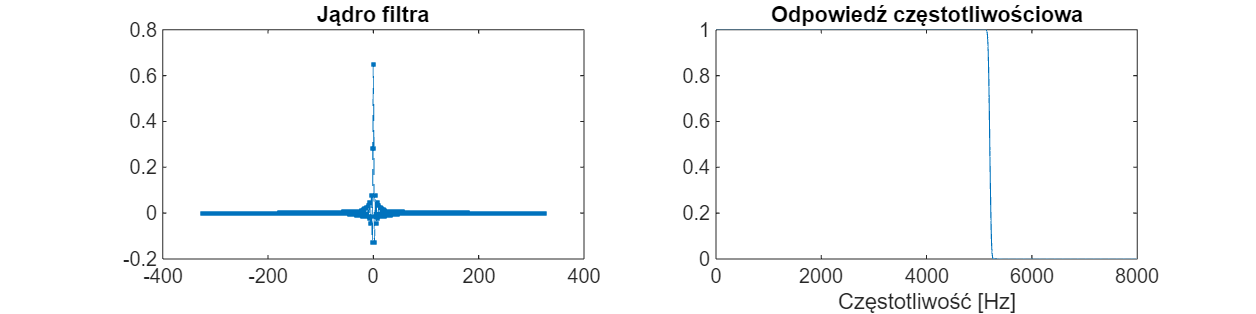

fc = 5200;   % częstotliwość odcięcia
fb = 100;   % stromość zbocza

F_low = f_lowpass(fc, fb, fs);
filtstat(F_low, fs);

#### Filtr górnoprzepustowy

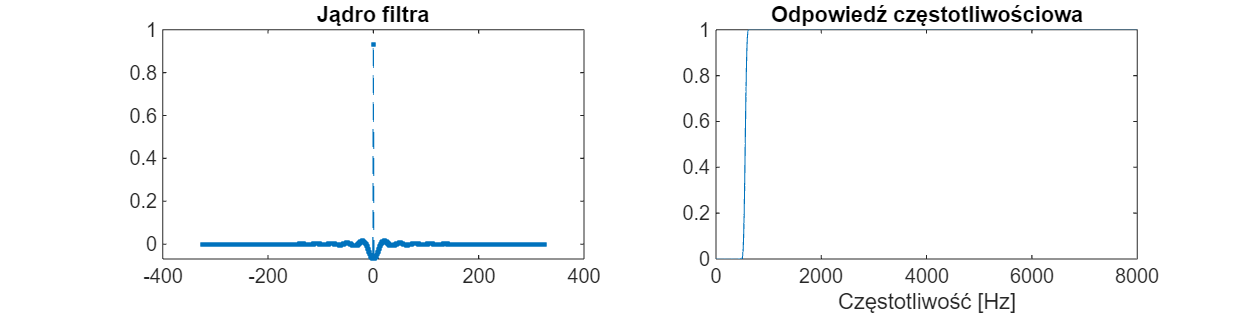

fc = 555;
F_high = f_highpass(fc, fb, fs);
filtstat(F_high, fs);

#### Filtry środkowoprzepustowe

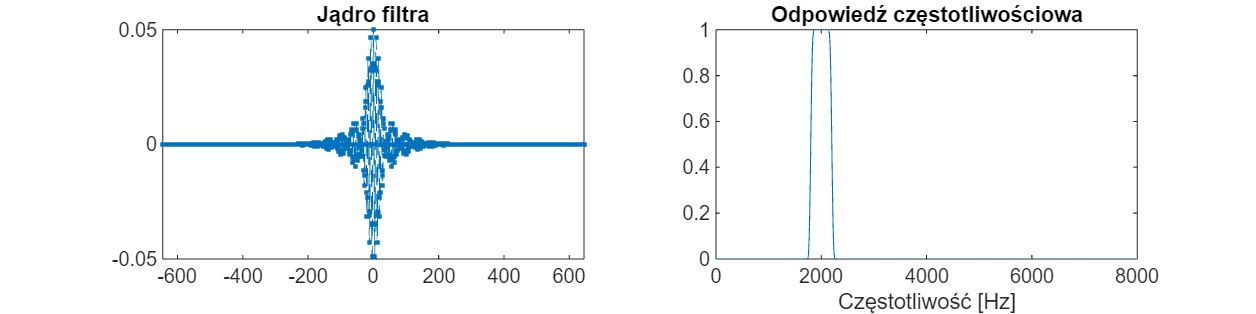

fl1 = 1800; fh1 = 2200;
fl2 =  3500; fh2 = 4600;

F1_band  = f_bandpass(fl1, fh1, fb, fs);
F2_band  = f_bandpass(fl2, fh2, fb, fs);

filtstat(F1_band, fs);

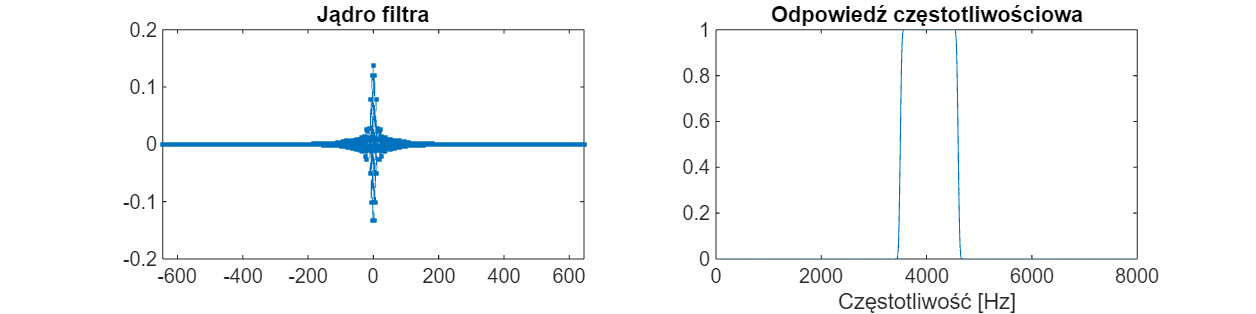

filtstat(F2_band, fs);

## Filtracja sygnału

Mając wygenerowane powyżej maski filtów środkowoprzepustowych można by było dokonać na nich inwersji spektralnej otrzymując w ten sposób filtry środkowozaporowe, a następnie odpowiednimi operacjami splotu utworzyć jedną maskę wspólnego filtra, który wyciąłby odpowiednie pasma. To podejście wymagałoby mniej obliczeń, gdyż wyznaczyłoby się splot (który jest kosztowny) masek tylko raz, a następnie wykonywałoby się tylko jeden splot z sygnałem. W tym przypadku jednak, skoro obliczenia i tak są prowadzone offline, pozwolono sobie na najprostsze zastosowanie odpowiednich sum i różnic splotów sygnału z poszczególnymi maskami filtrów. Jest to bardziej złożone obliczeniowo, ale łątwiejsze przy testowaniu różnych konfiguracji filtrów i ich ilości 

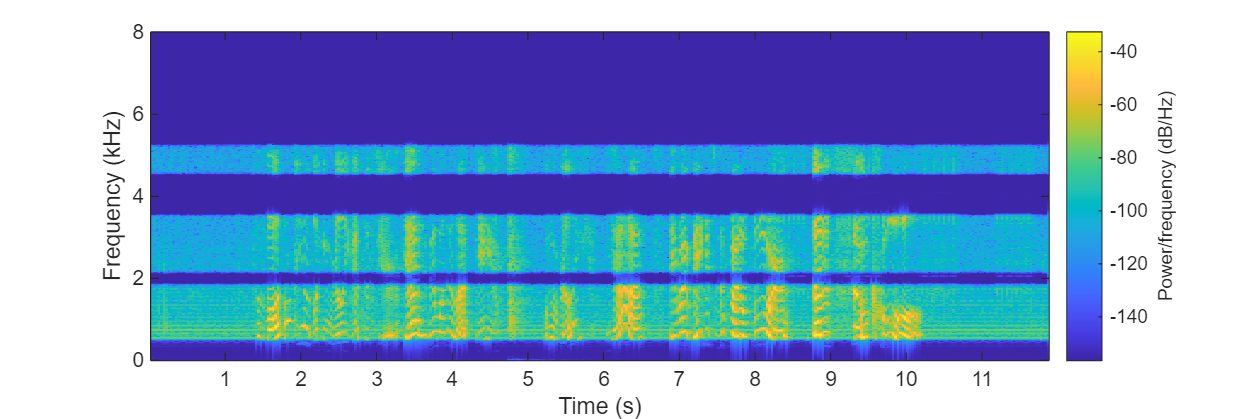

x_filtered =  conv(conv(x, F_high, 'same'), F_low, 'same') - conv(x, F1_band, 'same') - conv(x, F2_band, 'same') ;

win_size = 1024;
figure('Position', [10 10 1200 400]);
spectrogram(x_filtered, blackman(win_size), win_size/2, [], fs, 'yaxis')

Na spektrogramie widać, że sygnał został prawie całkowicie wycięty we wszystkich pasmach zaporowych. Wizualnie można stwierdzić, że częstotliwości graniczne filtrów zostały dobrane poprawnie, gdyż wycięto najbardziej znaczące harmoniczne przydźwięku sieciowego oraz dźwięku budzika. 

## Odtworzenie przefiltrowanego sygnału

sound(x_filtered, fs);

Na otrzymanym nagraniu nadal słychać cichy przydźwięk sieciowy, ale jest on znacznie słabszy niż poprzednio. Słychać, że nie jest to typowo niski brum, lecz jego kolejne wyższe harmoniczne. Niestety nie dałoby się wyciąć go w ten sposób bardziej, stosując jeszcze wyższe fc, gdyż wtedy znacząco ucięłoby się sygnał mowy, którego moc najbardziej skupiona jest w paśmie około 1-2kHz. Sygnał budzika został znacząco wytłumiony, jednakże słychać nadal delikatne "stukanie", jego dźwięk zmienił się zupełnie, gdyż zostały wycięte z widma jego główne prążki, a pozostały tylko mało znaczące składowe, które normalnie odpowiadałyby tylko za barwę dźwięku. Dźwięki samej rozmowy zostały przytłumione, jednak nadal można w pełni zrozumieć ich treść. Zastosowane górne pasmo 5,2kHz jest większe niż w telefonii, jednak przez wycięcie pozostałych trzech pasm dźwięk jest bardziej przytłumiony niż w przypadku rozmowy przez telefon.

## Zapis pliku wyjściowego

audiowrite('data/output.wav', x_filtered, fs);

## Implementacja filtrów

### Argumenty:

- fc - częstotliwość graniczna (Hz)

- fl, fh - częstotliwości graniczne filtra pasmowego (Hz)

- fb - szerokość pasma przejściowego (Hz)

- fs - częstotliwość próbkowania sygnału filtrowanego (Hz)

Na początku funkcji dokonywana jest normalizacja częstotliwości *fc* oraz *fb* względem częstotliwości próbkowania. Następnie obliczana jest długość maski filta *M*. Następnie w pętli wyliczane są kolejne wyrazy maski, przy czym środkowy wyraz jest wyliczany z innego wzoru, co pozwala uniknąć dzielenia przez 0.

function F = f_lowpass(fc, fb, fs)  
    fc = fc/fs;
    fb = fb/fs;

    M = round(2/fb)*2;
    h = zeros(1, M+1);

    for i = 0:M
        if i == M/2
            h(i+1) = 2*pi*fc;
            continue
        end
        h(i+1) = sin(2*pi*fc*(i-M/2))/(i-M/2)*(0.42-0.5*cos(2*pi*i/M)+0.08*cos(4*pi*i/M));
    end

    F = h/sum(h);
       
end

Filtr górnoprzepusowy jest otrzymywany na podstawie maski filtra dolnoprzepustowego o tej samej częstotliwości granicznej, poprzez dokonanie inwersji spektralnej, która polega na negacji wszystkich wyrazów maski oraz dodaniu 1 do środkowego wyrazu.

function F = f_highpass(fc, fb, fs)
    F = -f_lowpass(fc, fb, fs);
    F(round(length(F)/2)) = F(round(length(F)/2)) + 1;
end

Natomiast filtr środkowoprzepustowy otrzymuje się dokonując splotu na maskach odpwiednich filtrów dolno i górnoprzepustowego. W tej operacji uzyskuje się wektor o długości równej sumie długości obu masek minus jeden. Nie zastosowano tutaj argumentu *"same"* w funkcji *conv*, aby nie spowodować pogorszenia jakości filtru.

function F = f_bandpass(fl, fh, fb, fs)
    F = conv(f_lowpass(fh, fb, fs), f_highpass(fl, fb, fs));
end

## Funkcje wyświetlające dane

function filtstat(f, fs)
    nfft = 10000;
    
    f_ex = zeros(1, nfft);
    f_ex(1:size(f, 2)) = f;
        
    y = fft(f_ex);
    f_base = linspace(0, fs/2, nfft/2+1);
    amp = abs(y(1:nfft/2+1));
    phase = angle(y(1:nfft/2+1));
    
    figure('Position', [10 10 1200 300]);
    subplot(121);
    f_pad = [zeros(1, 5), f, zeros(1, 5)];
    t_pad = (1:length(f_pad)) - round(length(f_pad) / 2);
    plot(t_pad, f_pad, '.--');
    title("Jądro filtra");
    subplot(122);
    plot(f_base, amp);
    title("Odpowiedź częstotliwościowa");
    xlabel("Częstotliwość [Hz]");
end